# Example 3 - Computing the Torque Curve

`Goal:`` Estimate the torque curve as a function of the pole angle.`

`Result:`` Plots of the torque curve, and of the flux density at the maximum torque reached.`

## Prequisites

Making sure that a model has already been initialized.

if ~exist('motor', 'var')
    Example_01_Setting_up_a_Model;
    close all;
end

## `Background`

This example shows how to compute the torque curve of a synchronous machine, with a given current density. The curve is computed versus the *pole angle*, i.e. 90 degrees corresponding to id=0.

The curve is computed using magnetostatic analysis and with a single rotor position only, meaning it ignores the effects of eddy currents, and more importantly the effect of torque ripple. Nevertheless, it is an extremely fast way of getting an initial impression of the performance of the modelled machine.

### A note on conventions

Importantly, this example computes the torque curve using a single rotor position only, rotating the 3-phase (or m-phase in general) current vector. By contrast, other software may opt for the opposite approach - rotating the rotor against a constant current vector. 

## Initializations

We first begin by initializing a new [MagneticsProblem](https://www.emdtool.com/api/MagneticsProblem.html) object. Since we are being careful, we can use the `.new` static method, which caches the created object and speeds up subsequent calls to the same method with the same input.

problem = MagneticsProblem.new(motor);

Next, we defin the range of pole angles to analyse, and the rms current density to use,


angles = linspace(0, pi, 21); %pole angles to analyse
Jrms = 10e6; %current density Arms

Note: when analyzing electrically-excited machines, the following lines can be uncommented to set the rotor excitation.


%uncomment for electrically-excited machines
%{
Jfield = 3e6;
field_circuit = rotor.winding;
Ifield = Jfield * field_circuit.conductor_area_per_turn_and_coil();
field_circuit.set_source('uniform coil current', Ifield*ones(1, numel(angles)));
%}

Next, we are computing the phase currents corresponding to the rotating current vector

spec = stator.winding_spec;
Ipeak = sqrt(2)*Jrms * phase_circuit.conductor_area_per_turn_and_coil();
Is = spec.xy(Ipeak*[cos(angles); sin(angles)], 0);

and setting the currents as our excitation for the stator winding. We do this with the [`.set_source method of the PolyphaseCircuit class`](https://www.emdtool.com/api/PolyphaseCircuit.html#set_source-set-circuit-source), in this case specifying the `'uniform coil current' `option. As the title suggests, this enforces the coil current, or the current in each parallel path, assuming ideal uniform current distribution with no eddy effects modelled.

%setting source
phase_circuit = stator.winding;
phase_circuit.set_source('uniform coil current', Is);

Since we are dealing with magnetostatic analysis, we can only specify a uniform coil current as the excitation. Please note that the coil current and the phase current generally differ by the ratio of the parallel paths in the winding `spec.a`.

## Solving the problem

Next, we solve the problem using the same syntax as before.

%setting parameters
pars = SimulationParameters('rotorAngle', 0*angles/dim.p);

%solving problem
static_solution = problem.solve_static(pars);

Computing step/case 1 out of 21...
    Newton step 1, relative residual 1.
    Newton step 2, relative residual 1.4117.
     Relaxation automatically set to 0.9
    Newton step 3, relative residual 0.23289.
    Newton step 4, relative residual 0.060793.
    Newton step 5, relative residual 0.01949.
    Newton step 6, relative residual 0.0055904.
    Newton step 7, relative residual 0.0011613.
    Newton step 8, relative residual 0.00018506.
    Newton step 9, relative residual 1.3637e-05.
    Newton step 10, relative residual 4.3467e-07.
Computing step/case 2 out of 21...
    Newton step 1, relative residual 0.0051765.
    Newton step 2, relative residual 0.019648.
     Relaxation automatically set to 0.9
    Newton step 3, relative residual 0.0039825.
    Newton step 4, relative residual 0.00067198.
    Newton step 5, relative residual 6.2122e-05.
    Newton step 6, relative residual 2.5041e-06.
    Newton step 7, relative residual 8.7234e-08.
Computing step/case 3 out of 21...
    Ne

## Plotting the results

Finally, the remaining steps are to visualize the torque curve and the flux density.

First, we compute the torque

T = motor.compute_torque( static_solution );

Then, in order to make the analysis syntax here consistent for models with multiple airgaps, we compute the total torque with

T_total = sum(T,1);

In our example case, this does absolute nothing. However, multigap models generally return an array of torques, with the number of rows equal to the number of airgaps. Computing the column-wise sum then commonly yields the net torque, although complex models with multiple rotating components may require special care.

### Actual plots

With this out of the way, we can proceed into the actual plotting.

First, the torque curve

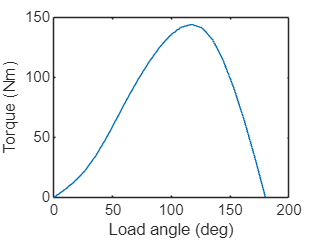

%plotting torque
figure(5); clf; hold on; box on;
plot(angles/pi*180, T);
xlabel('Load angle (deg)');
ylabel('Torque (Nm)');

and then the flux density distribution at the maximum torque reached.

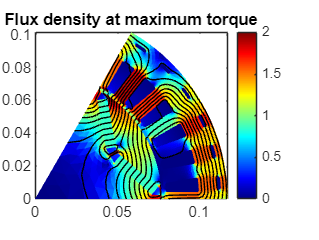

%plotting flux at maximum torque
figure(6); clf; hold on; box on;
[~, ind] = max(T);
motor.plot_flux(static_solution, ind);
title('Flux density at maximum torque');